# Generate Manhattan Boundary

Note that the Manhattan.shp is projected back to **WGS84 **from **NAD_1983_StatePlane_New_York_Long_Island_FIPS_3104_Feet** , using QGIS's **reproject tool**.

The source file used to generate Manhattan.shp is nyct2010.shp, which is open to public at  [https://www1.nyc.gov/site/planning/data-maps/open-data/districts-download-metadata.page](https://www1.nyc.gov/site/planning/data-maps/open-data/districts-download-metadata.page)

## Retrieve Manhattan tracts

nycshape=shaperead('nycshape\manhattan.shp',...
    'Selector',{@(BoroName) strcmpi(BoroName,'Manhattan'),'BoroName'},'UseGeoCoords',true) ;

## Form the whole Manhattan polygon from its tracts

[Latcells,Loncells]=polysplit(extractfield(nycshape,'Lat'),extractfield(nycshape,'Lon'));
[Latcells,Loncells]=poly2cw(Latcells,Loncells);
n=length(Latcells);
Lat=[];Lon=[];
for i=1:n   
    [Lat,Lon]=polybool('union',Lat,Lon,Latcells{i},Loncells{i});
end

## Simplify the border

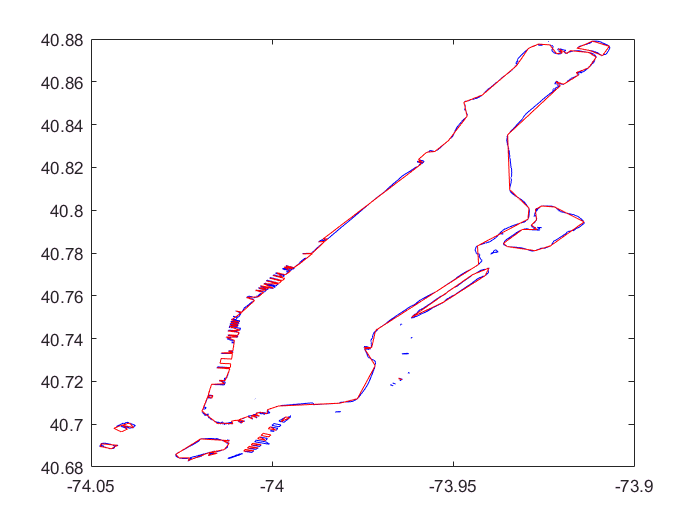

clf
[lat,lon]=reducem(Lat(:),Lon(:),0.001);
plot(Lon,Lat,'b-')
hold on
plot(lon,lat,'r')

## Trim Manhattan Boundary to Bounding Box

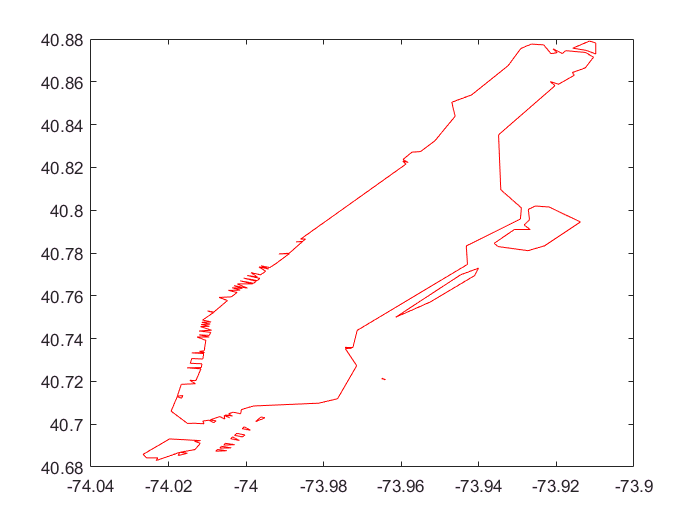

latlim=[40.680276,40.882530];
lonlim=[-74.036206,-73.909863];
[lat2,lon2]=poly2ccw(lat,lon);
[latTrimmed,lonTrimmed] = maptrimp(lat2,lon2,latlim,lonlim) ;
figure
plot(lonTrimmed,latTrimmed,'r')

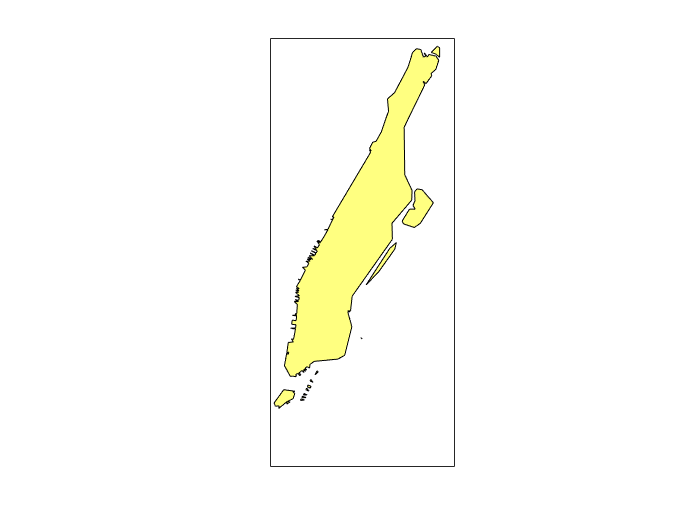

figure
axesm('lambert','MapLatLimit',[40.6,40.9],'MapLonLimit',[-74.1,-73])
geoshow(latTrimmed,lonTrimmed,'DisplayType','Polygon')

## Construct Geoshape Class: ManhattanBoundary

ManhattanBoundary = geoshape(latTrimmed,lonTrimmed,'Geometry','polygon')

ManhattanBoundary =  1×1 geoshape vector with properties:

 Collection properties:
     Geometry: 'polygon'
     Metadata: [1×1 struct]
 Vertex properties:
     Latitude: [1×220 double]
    Longitude: [1×220 double]


save('./nycshape/ManhattanBoundary.mat','ManhattanBoundary') 